# MAGEMin Equilibrium Path Calculator

Use MAGEMin to calculate stable phase equilibria along $P$,$T$-path at a given bulk composition.

clear all; close all;
addpath('./matlab');

## Specify run mode

Select equilibrium path, fractionation, assimilation, or combined assimilation/fractionation

RunMode = 'equilibrium';

## Specify starting composition

% Specify starting composition
OxdNames      = {'SiO2','Al2O3','CaO','MgO','FeOt','K2O','Na2O','TiO2','O','Cr2O3','H2O'};

% Select predefined composition 0-8, (leave on -1 to manually specify composition in table below
Chemistry.Predefined = nan;     % predefined compositions 
Chemistry.sys_in     = 'mol';                  % predefined in mol %

if isnan(Chemistry.Predefined)
    Chemistry.sys_in = 'wt';  %  set units for composition

    OxideFractions( 1) = 51.3122;  % SiO2
    OxideFractions( 8) = 1.7841;  % TiO2
    OxideFractions( 2) = 13.812;  % Al2O3
    OxideFractions(10) = 0.209;  % Cr2O3
    OxideFractions( 5) = 10.7646;  % FeOt
    OxideFractions( 4) = 6.0394;  % MgO
    OxideFractions( 3) = 11.312;  % CaO
    OxideFractions( 7) = 2.1487;  % Na2O
    OxideFractions( 6) = 0.3637;  % K2O
    OxideFractions(11) = 0;  % H2O
    OxideFractions( 9) = 0.25;  % O
end

Chemistry.OxProp  =  table(OxdNames(:),OxideFractions(:),'VariableNames',{'Oxide','mol %'});


## Specify Equilibrium Path

% Specify P,T path
P_max  =  1;  % maximum pressure [kbar]
P_min  =  1;  % minimum pressure [kbar]
P_stp  =  0;  % incrmnt pressure [kbar]

T_max  =  1200;  % maximum pressure [kbar]
T_min  =  800;  % minimum pressure [kbar]
T_stp  =  50;  % incrmnt pressure [kbar]

if ~P_stp || ~(P_max-P_min)  % isobaric path
    T_vec      =  (T_max:-T_stp:T_min).';
    P_vec      =   P_max.*ones(size(T_vec));
    isobaric   =  true;
    isothermal =  false;
    pathlbl    =  'isobaric';
elseif ~T_stp || ~(T_max-T_min)  % isothermal path
    P_vec      =  (P_max:-P_stp:P_min).';
    T_vec      =   T_max.*ones(size(P_vec));
    isothermal =  true;
    isobaric   =  false;
    pathlbl    =  'isothermal';
else
    nstp       =  max(round((P_max-P_min)/P_stp),round((T_max-T_min)/T_stp));
    P_vec      =  linspace(P_max,P_min,nstp).';
    T_vec      =  linspace(T_max,T_min,nstp).';
    isothermal =  false;
    isobaric   =  false;
    pathlbl    =  'PT';
end
TP_vec     = [T_vec,P_vec];
Points     =  1:size(T_vec,1);

## Run calculation

                %  How much info will be shown during computations?

% Set default values for computation
VerboseLevel                      = 0;        % set to create thermocalc-style output file
Computation.RefinementLevels      = 1;        % # of refinement levels
Computation.Verbose               = 0;        % How much info will be shown?
Computation.AllPoints             = 1;        % Do we compute with all points or not?
Computation.UseGammaEstimation    = 0;        % Use previous gamma or not?
Computation.NumRanks              = 1;        % # of processors if we compute in parallel
Computation.MPI_dir               = '/usr/local/bin';  % directory that has the MPI executable
Computation.RemoteServer          = false;    % perform all computations on a remote server?
Computation.MinPhaseFraction      = 3e-3;     % Minimum require phase fraction, before we take a phase into account
Computation.num_Neighbours        = 9;
Computation.Use_xEOS              = false;
Computation.Use_EMFrac            = false;
Computation.EOS_Method            = 'Average surrounding points';
Computation.MatlabOut             = 1;        % set output style to retrieve by ReadMatlabOutput_MAGEMin.m

% Determine if we use the BinaryBuilder/Julia binary or a locally compiled version of MAGEMin.
path_dylib=[];
path_bin=[];
path_julia=[];
if exist('environmental_variables','file')==2
    % yes, we did run the julia installation script @ some stage
    Computation.Julia_MAGEMin_binary  =   true;

    environmental_variables;                                    % run script

    Computation.path_dylib    = path_dylib;   % dynamic libraries
    Computation.path_bin      = path_bin;     % MAGEMin & mpiexec binaries
else
    Computation.Julia_MAGEMin_binary = false;
end

% Check if a local MAGEMin version is available
if exist('MAGEMin')==2 || exist('MAGEMin.exe')==2
    Computation.Local_MAGEMin_binary = true;
else
    Computation.Local_MAGEMin_binary = false;
end

% set binary toggle
if      Computation.Julia_MAGEMin_binary==true && Computation.Local_MAGEMin_binary==true
    Computation.BinaryMethod = 'Local';
elseif  Computation.Julia_MAGEMin_binary==true && Computation.Local_MAGEMin_binary==false
    Computation.BinaryMethod = 'Default';
elseif  Computation.Julia_MAGEMin_binary==false && Computation.Local_MAGEMin_binary==true
    Computation.BinaryMethod = 'Local';
else
    % No binary is available at all; switch color of button to
    % red
    app.Binary_Switch.FontColor=[1,0,0];
    Computation.BinaryMethod = 'none';

    % Call installation GUI
    app_install = Install_MAGEMin;
    while isvalid(app_install); pause(0.1); end

end

% retrieve version number of executable
if Computation.Julia_MAGEMin_binary==true || Computation.Local_MAGEMin_binary==true
    exe = MAGEMin_exe(Computation);

    command = [exe,' --version'];
    if Computation.Local_MAGEMin_binary==false
        command = add_dynamic_libs(command, Computation);
    end
    [stat, cmdout] = system(command);
    disp(cmdout)
    A=[];A=split(cmdout);
    MAGEMin_Version = A(2);

end

MAGEMin   1.2.3 [15/08/2022]




ComputeAllPoints    = true;
dlg.CancelRequested = false;
OUT = [];

% run MAGEMin calculations
disp(['Running MAGEMin along ',pathlbl,' path in ',RunMode,' mode.']);

Running MAGEMin along isobaric path in equilibrium mode.



switch RunMode
    case 'equilibrium' % equilibrium path
        [OUT, TP_vec, FailedSimulations, CancelComputation] = PerformMAGEMin_Simulation(OUT, Points, TP_vec, VerboseLevel, Chemistry, dlg, ComputeAllPoints, false, Computation);
    case 'fractionation'
        error('!!! Fractionation mode not yet implemented !!!')
    case 'assimilation'
        error('!!! Assimilation mode not yet implemented !!!')
    case 'assimilation/fractionation'
        error('!!! Assimilation-fractionation mode not yet implemented !!!')
end

zsh:1: no matches found: _pseudosection_output.*.*
./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=9 --Bulk=51.3122,13.812,11.312,6.0394,10.7646,0.3637,2.1487,1.7841,0.25,0.209,0,


command = 'export PATH=/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/bin:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/bin ;  export DYLD_LIBRARY_PATH=/Users/tokeller/.julia/artifacts/3de79395eef7694a5f90e9feb05eb575a59e69ae/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/lib/julia:/Users/tokeller/.julia/artifacts/c5444803422dfcb90ced251156d1d4e0188432d0/lib:/Users/tokeller/.julia/artifacts/10a7002eea557072e8e2ec81f16de1421d5bf667/lib:/Users/tokeller/.julia/artifacts/8bb12af145301381e13a50231a5110ad22c75313/lib:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib/julia:/Applications/Julia-1.7.app/Contents/Resources/julia/bin/../lib; ./MAGEMin --out_matlab=1 --Verb=0 --sys_in=wt --File=MAGEMin_input.dat --n_points=9 --Bulk=51.3122,13.812,11.312,6.0394,10.7646,0.3637,2.1487,1.7841,0.25,0.209,0,'

No matching processes belonging to you were found


ans = 1


Running MAGEMin 1.2.3 [15/08/2022] on 1 cores {
═══════════════════════════════════════════════
 Status             :            0 
 Mass residual      : +7.95103e-06
 Rank               :            0 
 Point              :            0 
 Temperature        :  +1200.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -998.228] (35 iterations, 116.19 ms)
 GAM = [-1047.193703,-1897.643720,-849.261837,-724.034756,-440.629959,-1111.428889,-971.054529,-1101.080171,-271.824732,-1418.205443]

 Phase :      liq      spn 
 Mode  :  0.99991  0.00017 
 Status             :            0 
 Mass residual      : +9.93916e-06
 Rank               :            0 
 Point              :            1 
 Temperature        :  +1150.00000	 [C] 
 Pressure           :     +1.00000	 [kbar]

 SOL = [G: -989.972] (61 iterations, 185.30 ms)
 GAM = [-1039.459937,-1888.543787,-841.399223,-717.001856,-430.325286,-1089.259083,-953.389524,-1091.611325,-271.363883,-1408.091484]

 Phase :     pl4T      li

ForwardSimulation_Time = 2.6821

ReadData_Time = 0.1598

## Plot phase data

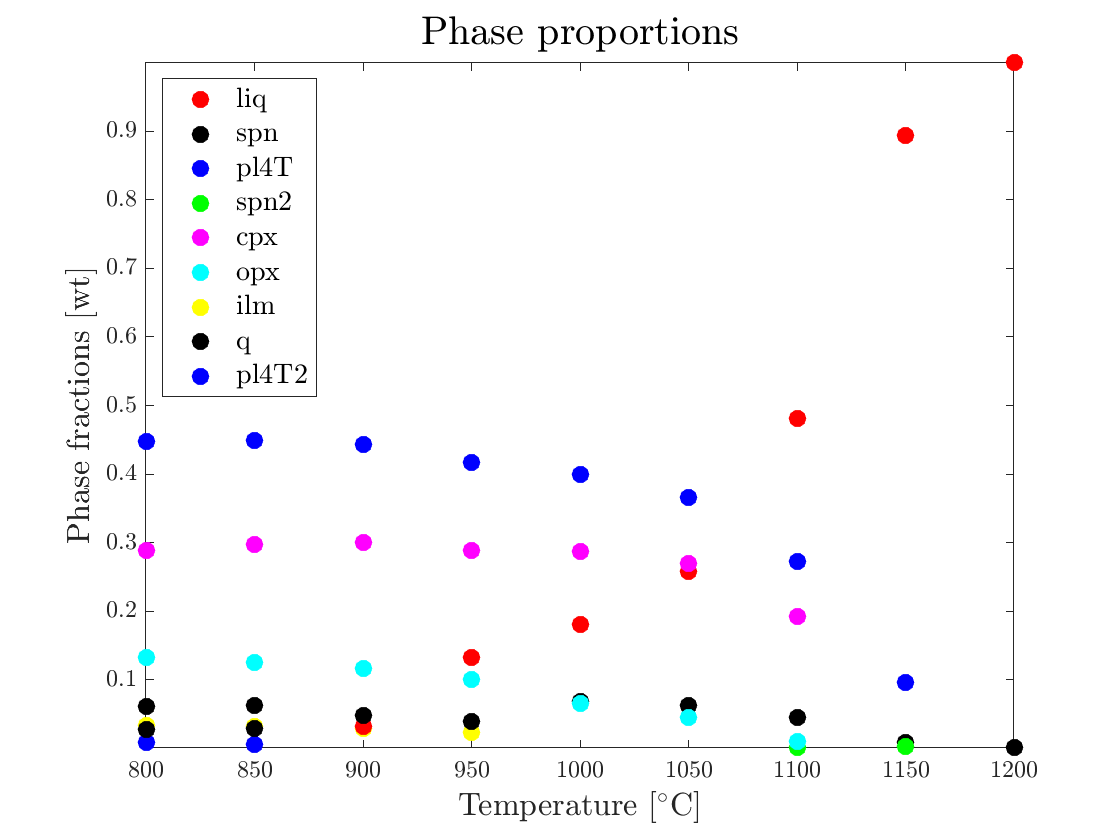

% prep phase colors
colors  = {'k' 'b' 'g' 'm' 'c' 'y' 'k' 'b' 'g' 'm' 'c' 'y'};
col.liq = 'r';
leg.liq = 'liq';
ic      = 1;

if isothermal
    xdata = OUT.P;
    xlbl = 'Pressure [kbar]';
elseif isobaric
    xdata = OUT.T;
    xlbl = 'Temperature [$^\circ$C]';
else
    xdata = OUT.T;
    xlbl = 'Temperature [$^\circ$C]';
end
    
% plot phase proportions
fig1 = figure(1); clf;
for ip=Points
    for is=1:OUT.numStablePhases(ip)
        phs = OUT.StablePhases{ip,is};
        if ~isfield(col,phs); col.(phs) = colors{ic}; ic = ic+1; end
        if ~isfield(leg,phs); leg.(phs) = phs; end
        p.(phs) = plot(xdata(ip),OUT.PhaseProps.(phs)(ip,1),'.','Color',col.(phs),'MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
    end
end
set(gca,'TickLabelInterpreter','latex','FontSize',12)
title('Phase proportions','Interpreter','latex','FontSize',20)
xlabel(xlbl,'Interpreter','latex','FontSize',16)
ylabel('Phase fractions [wt]','Interpreter','latex','FontSize',16)
pc   = struct2cell(p);
legc = struct2cell(leg);
legend([pc{:}],legc,'box','on','Interpreter','latex','FontSize',14,'Location','NorthWest')

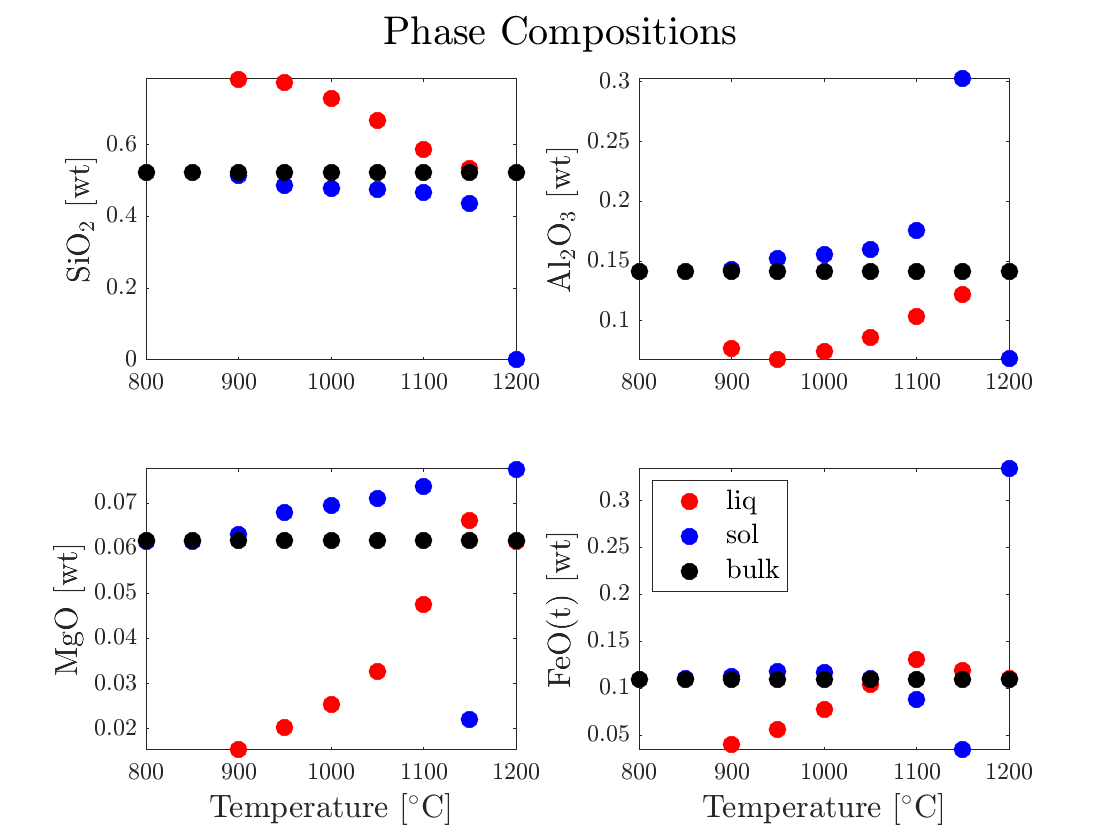



% plot phase and system compositions
fig2 = figure(2); clf;
subplot(2,2,1)  % SiO2
pliq = plot(xdata,OUT.OxideFractions.liq(:,1),'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
psol = plot(xdata,OUT.OxideFractions.sol(:,1),'b.','MarkerSize',30,'LineWidth',2.0);
psys = plot(xdata,OUT.OxideFractions.SYS(:,1),'k.','MarkerSize',30,'LineWidth',2.0);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
sgtitle('Phase Compositions','Interpreter','latex','FontSize',20)
ylabel('SiO$_2$ [wt]','Interpreter','latex','FontSize',16)

subplot(2,2,2)  % Al2O3
pliq = plot(xdata,OUT.OxideFractions.liq(:,2),'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
psol = plot(xdata,OUT.OxideFractions.sol(:,2),'b.','MarkerSize',30,'LineWidth',2.0);
psys = plot(xdata,OUT.OxideFractions.SYS(:,2),'k.','MarkerSize',30,'LineWidth',2.0);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
ylabel('Al$_2$O$_3$ [wt]','Interpreter','latex','FontSize',16)

subplot(2,2,3)  % MgO
pliq = plot(xdata,OUT.OxideFractions.liq(:,4),'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
psol = plot(xdata,OUT.OxideFractions.sol(:,4),'b.','MarkerSize',30,'LineWidth',2.0);
psys = plot(xdata,OUT.OxideFractions.SYS(:,4),'k.','MarkerSize',30,'LineWidth',2.0);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
xlabel(xlbl,'Interpreter','latex','FontSize',16)
ylabel('MgO [wt]','Interpreter','latex','FontSize',16)

subplot(2,2,4)  % FeO(t)
pliq = plot(xdata,OUT.OxideFractions.liq(:,5),'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
psol = plot(xdata,OUT.OxideFractions.sol(:,5),'b.','MarkerSize',30,'LineWidth',2.0);
psys = plot(xdata,OUT.OxideFractions.SYS(:,5),'k.','MarkerSize',30,'LineWidth',2.0);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
xlabel(xlbl,'Interpreter','latex','FontSize',16)
ylabel('FeO(t) [wt]','Interpreter','latex','FontSize',16)
legend([pliq,psol,psys],{'liq','sol','bulk'},'box','on','Interpreter','latex','FontSize',14,'Location','NorthWest')

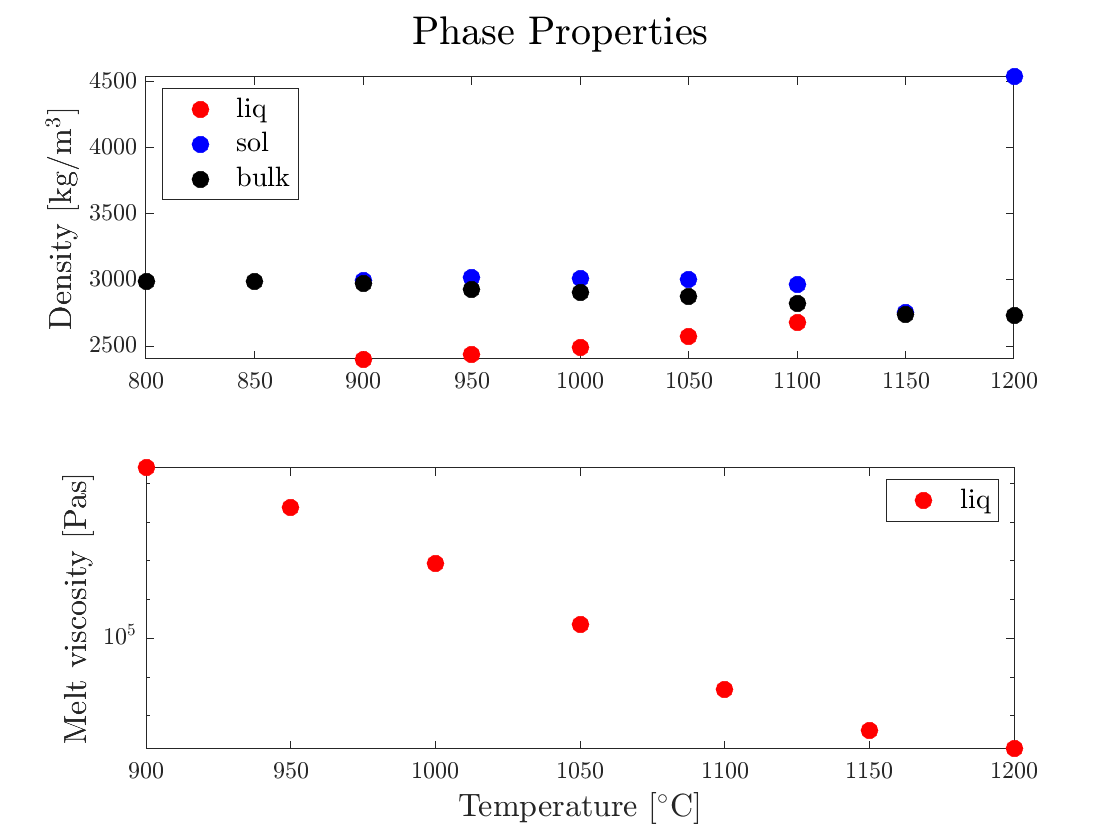


% plot phase and system densities, melt viscosity
fig3 = figure(3); clf;
subplot(2,1,1);
pliq = plot(xdata,OUT.Density.liq,'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
psol = plot(xdata,OUT.Density.sol,'b.','MarkerSize',30,'LineWidth',2.0);
psys = plot(xdata,OUT.Density.SYS,'k.','MarkerSize',30,'LineWidth',2.0);
set(gca,'TickLabelInterpreter','latex','FontSize',12)
sgtitle('Phase Properties','Interpreter','latex','FontSize',20)
ylabel('Density [kg/m$^3$]','Interpreter','latex','FontSize',16)
legend([pliq,psol,psys],{'liq','sol','bulk'},'box','on','Interpreter','latex','FontSize',14,'Location','NorthWest')

% plot melt viscosity
subplot(2,1,2)
pliq = semilogy(xdata,OUT.Viscosity.liq,'r.','MarkerSize',30,'LineWidth',2.0); axis tight; box on; hold on;
set(gca,'TickLabelInterpreter','latex','FontSize',12)
xlabel(xlbl,'Interpreter','latex','FontSize',16)
ylabel('Melt viscosity [Pas]','Interpreter','latex','FontSize',16)
legend(pliq,'liq','box','on','Interpreter','latex','FontSize',14)